# Sinusfahrt zur Abschätzung der Kameraverzögerung

Dieses Skript dient der Ermittlung der Verzögerung der Kameradaten durch Berechnung der Roboterposition, Packen und Senden des UDP-Datenpakets.

Hierzu wird der Roboter in x-Achse mit einem Sin()-förmigen Geschwindikeitsverlauf angestuert. Die Verzögerung ermittelt sich entsprehcend aus der Pjhasendifferenz zwischen Encoderdaten und Kameradaten.

## Einlesen des Datensatzes

##  & Filtern der Encoder- und Kameradaten

clear all;

%Zu importierende Datei auswählen
filename = "sinusfahrt.csv";
%Importieren und nicht relevante Informationen entfernen
data = readtable(filename);
%data([1:359],:)=[];

%plot(table2array(data(:,"vXFromMotor")))


% % Encoderdaten Geschwindigkeit in x filtern/glaetten moving mean windows size 80
% data = smoothdata(data,"movmean",20,"DataVariables","vXFromMotor");

% Fill outliers
% data = filloutliers(data,"linear","mean","DataVariables","vYFromMotor");
% data = filloutliers(data,"linear","mean","DataVariables","vXFromMotor");

% % Smooth input data
% data = smoothdata(data,"movmean",20,"DataVariables","vYFromMotor");

% Fill outliers
% data = filloutliers(data,"linear","ThresholdFactor",20,...
%     "DataVariables","vThetaFromMotor");

% % Smooth input data
% data = smoothdata(data,"movmean",20,"DataVariables","vThetaFromMotor");

% Fehlstellen (Nullwerte der Kamera) entfernen
data = filloutliers(data,"linear","movmedian",630,"DataVariables","camX");

% glaetten der Kameradaten x-Position moving mean windows size 50
data = smoothdata(data,"movmean",50,"DataVariables","camX");

% Fehlstellen in den CamTheta Daten entfernen
data = filloutliers(data,"linear","mean","DataVariables","camTheta");

% Glaetten/Filtern der CamTheta Daten. Local Quadratic regression windows
% size 200
data = smoothdata(data,"loess",200,"DataVariables","camTheta");

## Transformieren der Robotergeschwindigkeiten in globale Geschwindigkeiten

Theta = -2.95731687545776;
TMat = [cos(Theta)    -sin(Theta)   0;
        sin(Theta)    cos(Theta)    0;
        0                   0         1]

TMat =    -0.9831    0.1832         0
   -0.1832   -0.9831         0
         0         0    1.0000


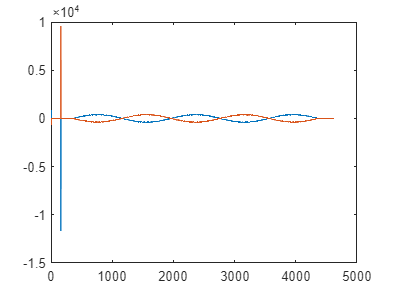


vXFromMotor = table2array(data(:,"vXFromMotor"));
vYFromMotor = table2array(data(:,"vYFromMotor"));
vThetaFromMotor = table2array(data(:,"vThetaFromMotor"));
vFromMotor = [vXFromMotor vYFromMotor vThetaFromMotor];
figure()
plot(vXFromMotor); hold on
vtf = vFromMotor*transpose(TMat);

plot(vtf(:,1));
hold off

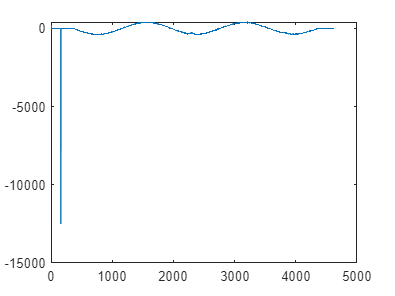

vtf = zeros(height(data),3);
for row=1:height(data)
    Theta = data{row,"camTheta"};
    TMat = [cos(Theta)    -sin(Theta)   0;
            sin(Theta)    cos(Theta)    0;
            0             0             1];
    vXFromMotor = data{row,"vXFromMotor"};
    vYFromMotor = data{row,"vYFromMotor"};
    vThetaFromMotor = data{row,"vThetaFromMotor"};
    vFromMotor = [vXFromMotor vYFromMotor vThetaFromMotor];
    vtf(row,:) = vFromMotor*transpose(TMat);
end

plot(vtf(:,1));
hold off

## Fit auf Sinus

yi = vtf(330:4378,1)

yi =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


xi = [0:1:4378-330]/1000

xi =          0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


length(yi)

ans = 4049

length(xi)

ans = 4049


fnc = @(x, b) (b(1)*sin(b(2)*x-b(3))) 

fnc = function_handle with value:
    @(x,b)(b(1)*sin(b(2)*x-b(3)))


fit = @(b)(sum((fnc(xi,b)-yi').^2))

fit = function_handle with value:
    @(b)(sum((fnc(xi,b)-yi').^2))


b0 = [377, 2*pi/1.6, pi];
bopt = fminsearch(fit, b0)

bopt =   373.5385    3.9248    3.2658


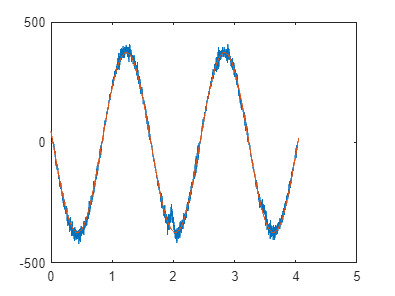


figure();
plot(xi, yi);
hold on
plot(xi, fnc(xi,bopt))

## Filtern der Encoder- und Kameradaten

camX = table2array(data(:,"camX"));
% % % windowSize = 50; 
% % % b = (1/windowSize)*ones(1,windowSize);
% % % a = 1;
% % % camXfilt = filter(b,a,camX);
oldCamX = 0;
for row = 1 : length(camX)
    if camX(row) == 0
        camX(row) = oldCamX;
    else 
        oldCamX = camX(row);
    end
end

## Geschwindikeiten aus Kameraposen berechnen

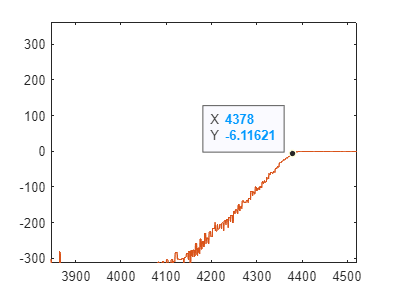

camX = table2array(data(:,"camX"));
camvX = data(:,"camX");
oldCamX = camX(1);
%camvX = zeros(length(camX),1);
%for row=1:length(camX)
%    if row > 1
%%        camvX{row,:} = (data{row,"camX"}-data{row-1,"camX"})/10e-3;
%    else
%        camvX{row,:} = 0;
%    end
    %oldCamX = camX(row);
%end
plot(table2array(camvX)); hold on
plot(diff(camX)/10e-3)

## Plotten

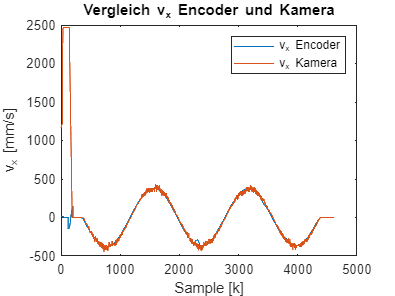

taskTS = 10e-3; %plc Task sample time in sec (10ms)
camvX=diff(camX)/taskTS;
hold off; plot(vtf(:,1));hold on; plot(camvX);
legend("v_x Encoder","v_x Kamera")
xlabel("Sample [k]"); ylabel("v_x [mm/s]");
title("Vergleich v_x Encoder und Kamera");

% Ergebnis 13-15 Samples Delay entsprechend 130-150ms. Orientiert am
% Nulldurchgang
hold off

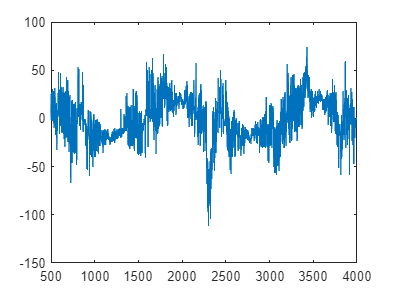

plot(camvX-vtf(1:length(vtf)-1,1))
xlim([500 4000])

function x = f1(x)
    x = sin(x)
end
